%  case2solution.m

## Set up data and adjacency matrices

D=[-6.5 -6.5 -6.5 -6.5 -2.5 -2.5 -.75 -.75 3.25 3.25  4.5 4.5  6.5 6.5 6.5  6.5;
   -2   -2   .5   .5   .5   .5    2    2    2    2   .5  .5   .5  .5  -2   -2;
 -2.5  2.5  2.5 -2.5 -2.5  2.5 -2.5  2.5 -2.5  2.5 -2.5 2.5 -2.5 2.5 2.5 -2.5;
    1    1    1    1    1    1    1    1    1    1    1   1    1   1   1    1];


ADJ=[ 0 1 0 1  0 0 0 0  0 0 0 0  0 0 0 1;
      1 0 1 0  0 0 0 0  0 0 0 0  0 0 1 0;
      0 1 0 1  0 1 0 0  0 0 0 0  0 0 0 0;
      1 0 1 0  1 0 0 0  0 0 0 0  0 0 0 0;
    
      0 0 0 1  0 1 1 0  0 0 0 0  0 0 0 0;
      0 0 1 0  1 0 0 1  0 0 0 0  0 0 0 0;
      0 0 0 0  1 0 0 1  1 0 0 0  0 0 0 0;
      0 0 0 0  0 1 1 0  0 1 0 0  0 0 0 0;
      
      0 0 0 0  0 0 1 0  0 1 1 0  0 0 0 0;
      0 0 0 0  0 0 0 1  1 0 0 1  0 0 0 0;
      0 0 0 0  0 0 0 0  1 0 0 1  1 0 0 0;
      0 0 0 0  0 0 0 0  0 1 1 0  0 1 0 0;
      
      0 0 0 0  0 0 0 0  0 0 1 0  0 1 0 1;
      0 0 0 0  0 0 0 0  0 0 0 1  1 0 1 0;
      0 1 0 0  0 0 0 0  0 0 0 0  0 1 0 1;
      1 0 0 0  0 0 0 0  0 0 0 0  1 0 1 0];

## question 1a

center of projection at (a,b,c)

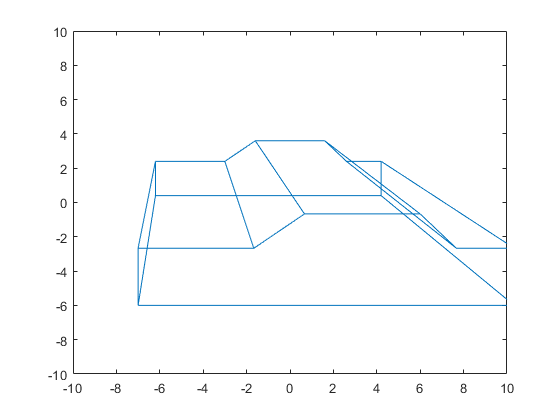

b=-5;c=10;d=10;
  
P=[1 0 -b/d 0;
   0 1 -c/d 0;
   0 0   0  0;
   0 0 -1/d 1];
 
%calculate projected coordinates
D2=P*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);

%pause

## question 1b

center of projection at (a,b,c)

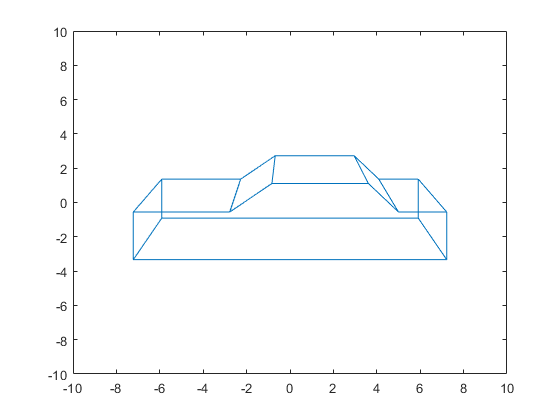

b=0;c=10;d=25 ;
P=[1 0 -b/d 0;
   0 1 -c/d 0;
   0 0   0 0;
   0 0 -1/d 1];
 
%calculate projected coordinates
D2=P*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);


%pause

## Question 2. Use same center of projection but rotate

30 degrees around y-axis

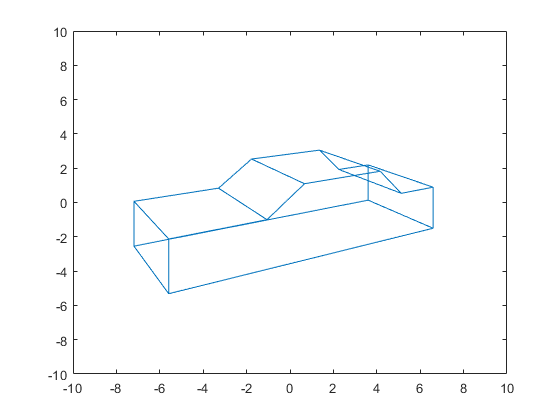

yrot=30*pi/180;   % angle in radians
Ry=[cos(yrot)  0 sin(yrot)  0;
    0          1      0     0;
    -sin(yrot) 0 cos(yrot)  0;
    0          0     0      1];

D2=P*Ry*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);


%pause

## Question 3. Rotate 45 degree about z-axis

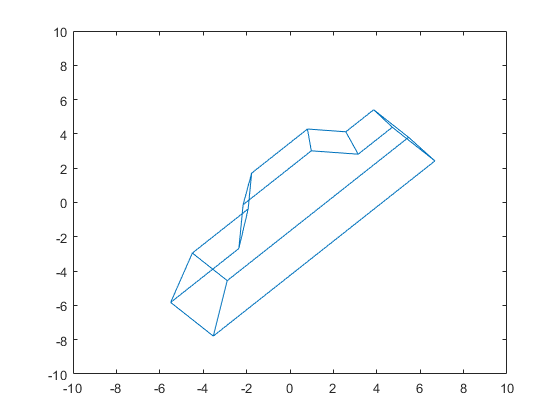

zrot=45*pi/180;
Rz=[cos(zrot)   -sin(zrot)  0    0;
    sin(zrot)    cos(zrot)  0    0;
        0             0     1    0;
        0             0     0    1];
    
D2=P*Rz*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);


%pause

## Question 4. Zoom 150%

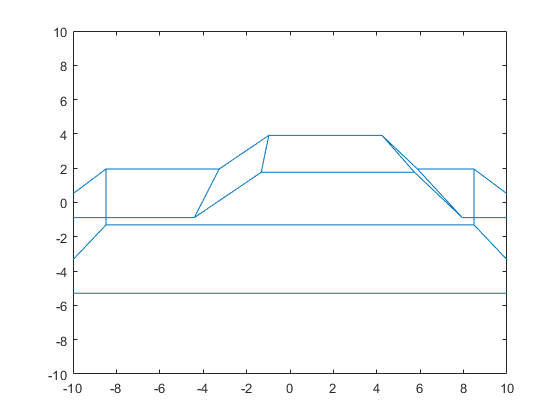

f=1.5;
zoom=[f 0 0 0;
      0 f 0 0;
      0 0 f 0;
      0 0 0 1];

D2=P*zoom*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);

## Presentation graph

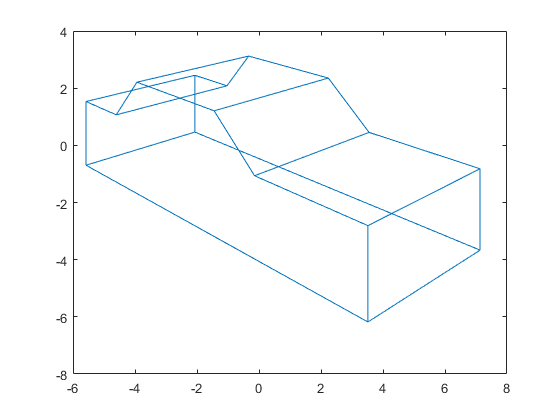

yrot=1*pi/180;   % angle in radians
Ry=[cos(yrot)  0 sin(yrot)  0;
    0          1      0     0;
    -sin(yrot) 0 cos(yrot)  0;
    0          0     0      1];


while 1>0   % loop until terminated with ctrl-c
    D=Ry*D;
    D2=P*D;
    D2(1,:)=D2(1,:)./D2(4,:);
    D2(2,:)=D2(2,:)./D2(4,:);
    xy=D2(1:2,:)';
    gplot(ADJ,xy);
    axis([-10 10 -10 10]);
    pause(0.01)
end